# **Experiment 1: Number of Anomalies vs AUC**

clear % Add repository folders to path
mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
folder_path = strsplit(mfilePath,filesep);
repo_path = join([folder_path(1:end-2)],filesep);
repo_path = repo_path{1};
data_path = [repo_path,filesep,'data'];
src_path = [repo_path,filesep,'src'];
tenandet_path = [repo_path,filesep,'tenandet'];
testbench_path = [repo_path,filesep,'testbench'];
addpath(genpath(data_path), genpath(src_path),genpath(tenandet_path), genpath(testbench_path));
clear folder_path mfilePath repo_path data_path testbench_path src_path tenandet_path

## Load NYC Data:

sizes = [144,7,52,10];                                      % Load NYC data 
load nyc_tensors.mat
load regions.mat
arrs = squeeze(sum(reshape(arrs,6,24,365,[]),1)); 
Y = double(reshape(arrs(:,1:364,regions), 24, 7, 52,[]));   % Select 81 zones
Y(:,1,53,:) = arrs(:,365,regions);
Y(:,2:7,53,:) = mean(Y(:,2:7,1:52,:),3);                 % Fill in the last week with the mean of other weeks
sz = size(Y);
% dropoffs = Y;
% clear Y

cs = 4;
NoA = [25,50,100,250,500,750];
% NoA = 100*NoAL;
duration = 6;
sz = size(Y);
NoT = 1;
len_NoA = length(NoA);
% outlying_scores_of = zeros(len_NoA,NoT,53,81);
auc_of = zeros(len_NoA,NoT);
auc_raw = zeros(len_NoA,NoT);
auc_ocsvm = zeros(len_NoA, NoT);


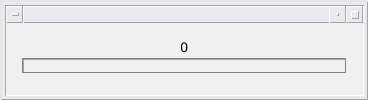


% parpool('local',81);
tic
f = waitbar(0, '0');

for i=1:len_NoA
    for j=1:NoT
        

        number_anomaly = NoA(i);
        length_anomaly = duration;
        amplitude_anomaly = cs;
        missing_days = 0;
        seed = j;
        [X, ~, Yn, removed_inds, mat_anomaly] = ...
            gendata(sz, number_anomaly, length_anomaly, amplitude_anomaly, ...
                    Y, missing_days, false, seed);
        % Apply LOSS algorithm
        param = set_params(Yn);
        param.lambda= 0.075;% 1/(24*7*53);
        param.gamma= 0.075; % 1/(24*7*53);
        param.err_tol=1e-4;
        param.max_iter=150;
        [L,S]= loss(Yn, param);
        
        
        Sn = cell(53,81);
        olyings = zeros(53,81);
        for k=1:81
            for p=1:53
                Sn{p,k}=squeeze(S(:,:,p,k));
            end
        end

        parfor k=1:81
            for p=1:53
                z = Sn{p,k};
                [OS, Or]= outlying_function2(z,Sn(:,k),30,1e-3,0);
                olyings(p,k)= OS;
            end
        end
        
        anomaly_score = feature_scorer(olyings, S, false);
        s = abs(anomaly_score(:));
        label = X(:);
        classNames = [0;1];
        score = [-s,s];
        rocObj = rocmetrics(label, score, classNames);
        auc_of(i,j) = rocObj.AUC;
        rocObj = rocmetrics(label, [-abs(S(:)),abs(S(:))], classNames);
        auc_raw(i,j) = rocObj.AUC;
        anomaly_score = one_class_svm(Yn);

    end
    waitbar(i/len_NoA,f, [num2str(toc/60),' minutes elapsed.']);
end

Max iter


Unrecognized function or variable 'feature_scorer_nyc'.

f = figure();

ans =     0.6245    0.6245


plot(NoA, auc_of, label='w/ Outlying function');
plot(NoA, auc_raw, label='');
% plot(rocObj)

outlying_score_y = zeros(53,81);
Sn = cell(53,81);
for l = 1:81
for w = 1:53
    Sn{w,l} = squeeze(Yn(:,:,w, l));
end
end
tic
f = waitbar(0, '0');

f =   Figure (TMWWaitbar) with properties:

      Number: []
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [825 453 270 56.2500]
       Units: 'points'

  Show all properties


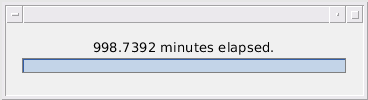

for l = 1:81
for w = 1:53
    z = Sn{w,l};
    [OS, ~] = outlying_function2(z,Sn(:,l),60,1e-3,0);
    outlying_score_y(w,l) = OS;
end
waitbar(l/81,f, [num2str(toc/60),' minutes elapsed.']);
end


% outlying_score = abs(outlying_score);
% outlying_score(isnan(outlying_score)) = 0;
% outlying_score(isinf(outlying_score)) = 0;
OScore_y = zeros(24,7,53,81);
for l=1:81
    for w=1:53
        OScore_y(:,:,w,l) = (S(:,:,w,l)~=0)* outlying_score_y(w,l);
    end
end